%EMAG Lab 2 ---- Part 1
%Constants
epsilon_0 = 8.85E-12;
mu_0 = 4E-7*pi;
zero = zeros(360);


%Given
epsilon_r_1 = 1;
epsilon_r_2 = 8;
theta_i = linspace(0,90,360);
theta_i_rad = pi*theta_i/180;



%Find
epsilon_1 = epsilon_r_1*epsilon_0;
epsilon_2 = epsilon_r_2*epsilon_0;
eta_1 = sqrt(mu_0/epsilon_1);
eta_2 = sqrt(mu_0/epsilon_2);

theta_tr_rad = sin(theta_i_rad)*sqrt(epsilon_r_1/epsilon_r_2);
theta_tr_rad = asin(theta_tr_rad);

gamma_perp = eta_2*cos(theta_i_rad)-eta_1*cos(theta_tr_rad);
gamma_perp = gamma_perp./(eta_2*cos(theta_i_rad)+eta_1*cos(theta_tr_rad));
tau_perp = 2*eta_2*cos(theta_i_rad);
tau_perp = tau_perp./(eta_2*cos(theta_i_rad)+eta_1*cos(theta_tr_rad));

gamma_par = eta_2*cos(theta_tr_rad) - eta_1*cos(theta_i_rad);
gamma_par = gamma_par./(eta_2*cos(theta_tr_rad) + eta_1*cos(theta_i_rad));
tau_par = 2*eta_2*cos(theta_i_rad);
tau_par = tau_par./(eta_2*cos(theta_tr_rad) + eta_1*cos(theta_i_rad));

R_perp = abs(gamma_perp).^2;
T_perp = abs(tau_perp).^2;
T_perp = T_perp.*((eta_1*cos(theta_tr_rad))./(eta_2.*cos(theta_i_rad)));

R_par = abs(gamma_par).^2;
T_par = abs(tau_par).^2;
T_par = T_par.*((eta_1*cos(theta_tr_rad))./(eta_2.*cos(theta_i_rad)));

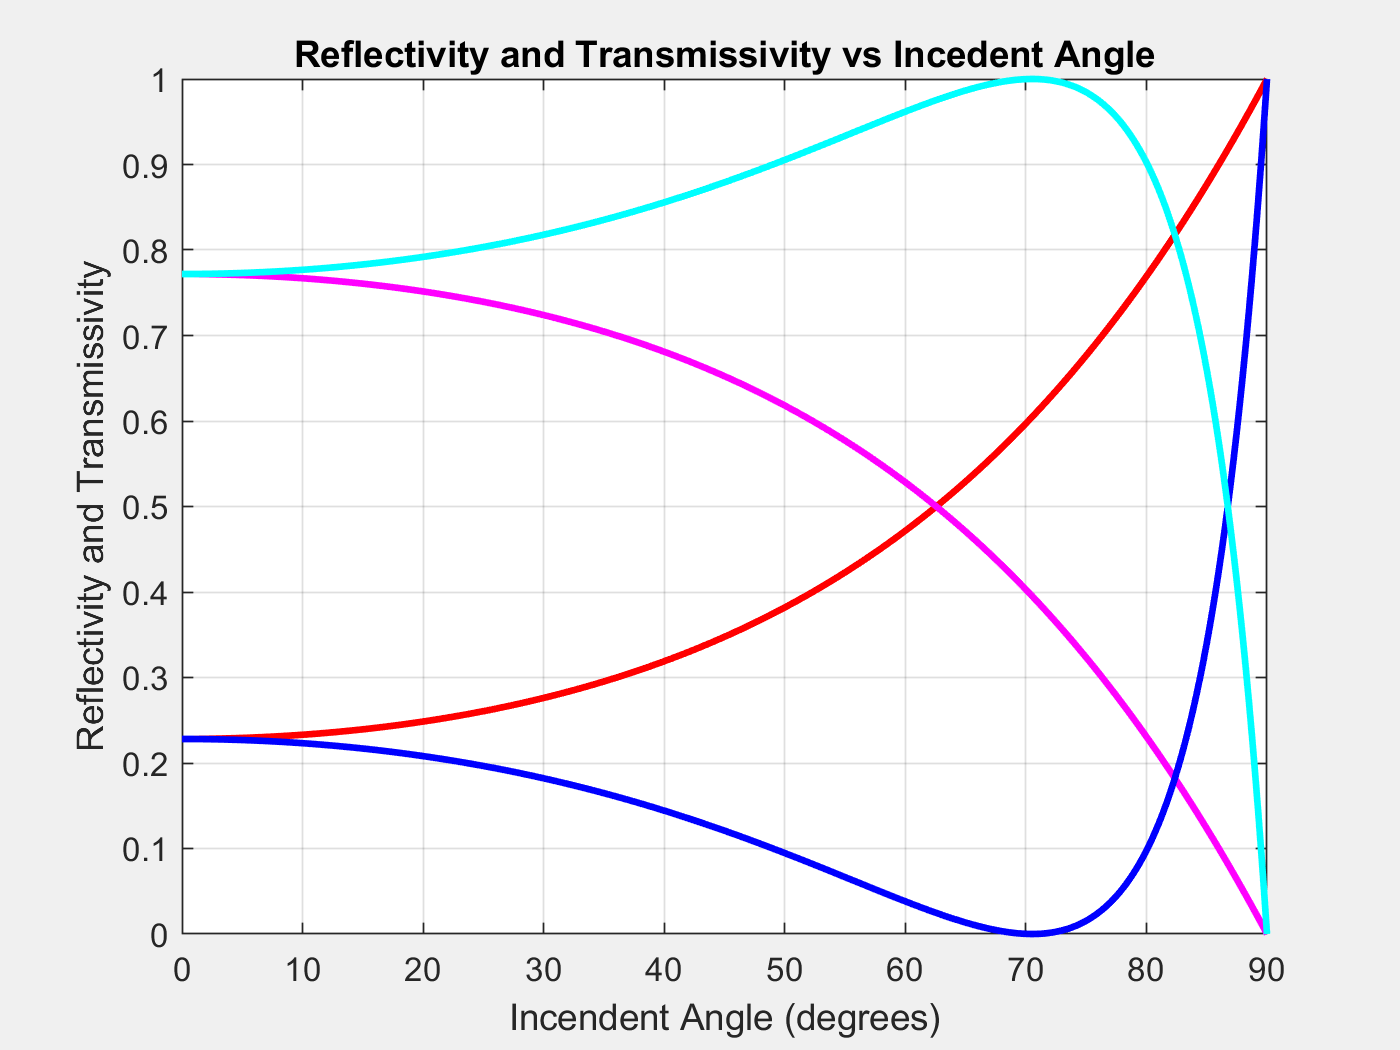


%Plotting
set(gcf,'Visible','on')
plot(theta_i, R_perp, 'r', 'LineWidth', 2)
hold on
plot(theta_i, T_perp, 'm', 'LineWidth', 2)
plot(theta_i, R_par, 'b', 'LineWidth', 2)
plot(theta_i, T_par, 'c', 'LineWidth', 2)
grid on
title('Reflectivity and Transmissivity vs Incedent Angle')
xlabel('Incindent Angle (degrees)')
ylabel('Reflectivity and Transmissivity')

%3D Plotting
hold off
set(gcf,'Visible','on')
p1 = plot3(theta_i, R_perp, T_perp, 'r', 'LineWidth', 2, 'DisplayName', 'TE')

p1 =   Line (TE) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×360 double]
              YData: [1×360 double]
              ZData: [1×360 double]

  Show all properties


hold on
p2 = plot3(theta_i, R_perp, zero, 'r', 'LineWidth', 2)

p2 =   360×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line

p3 = plot3(theta_i, zero, T_perp, 'r', 'LineWidth', 2)

p3 =   360×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


p4 = plot3(theta_i, R_par, T_par,'b', 'LineWidth', 2, 'DisplayName', 'TM')

p4 =   Line (TM) with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×360 double]
              YData: [1×360 double]
              ZData: [1×360 double]

  Show all properties


p5 = plot3(theta_i, R_par, zero, 'b', 'LineWidth', 2)

p5 =   360×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line

p6 = plot3(theta_i, zero, T_par, 'b', 'LineWidth', 2)

p6 =   360×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line

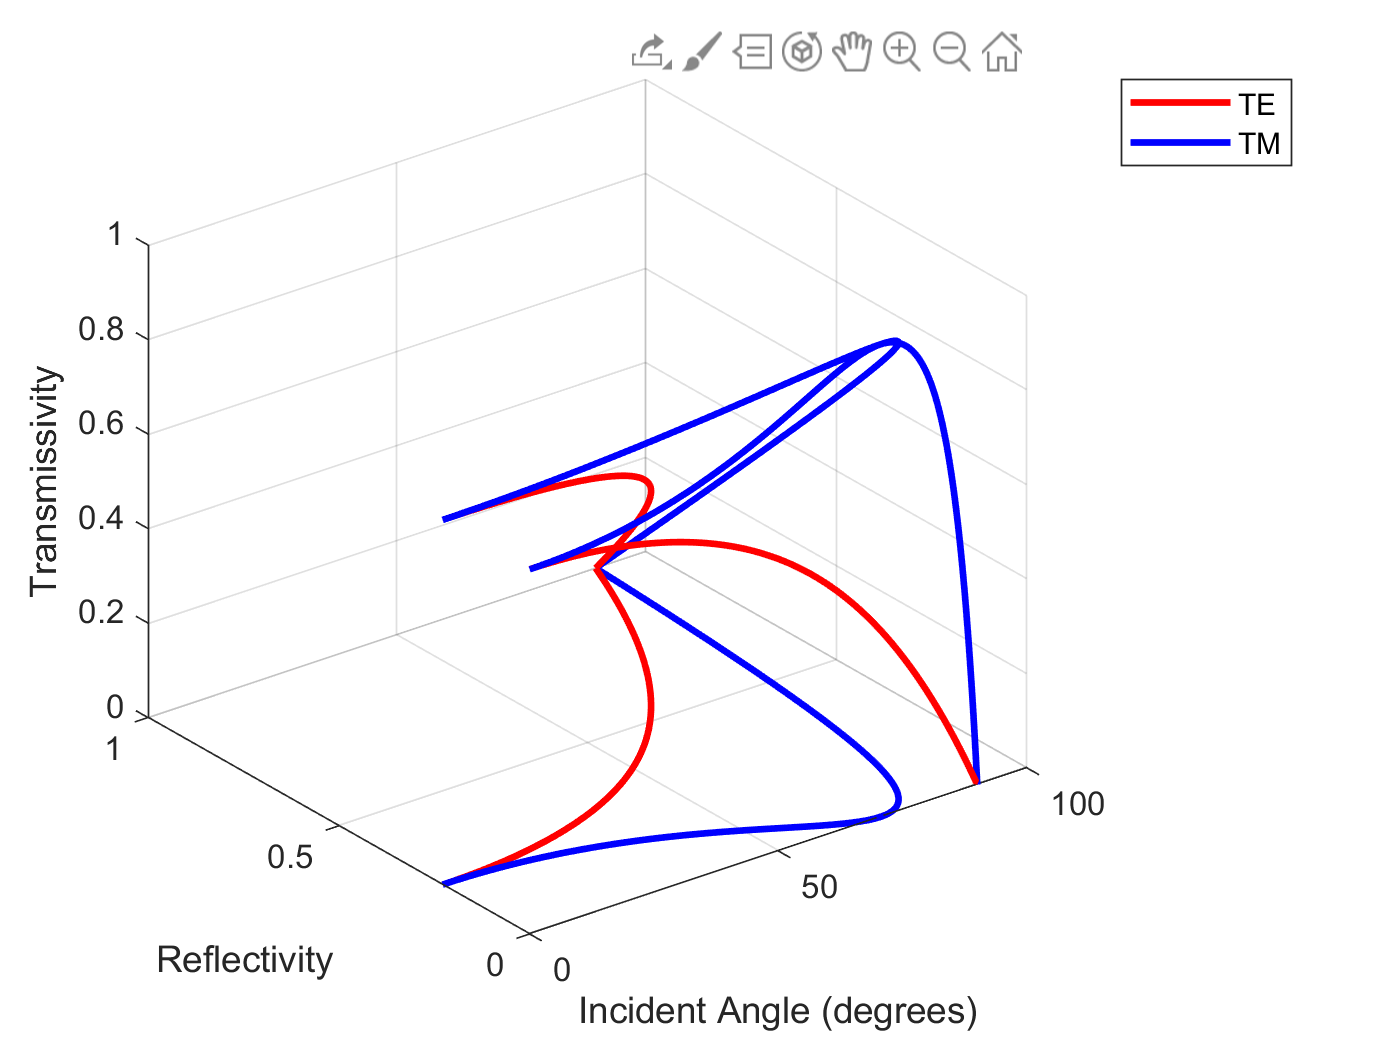


grid on
xlabel('Incident Angle (degrees)')
ylabel('Reflectivity')
zlabel('Transmissivity')
legend([p1,p4])